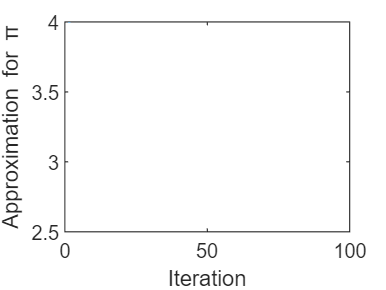

% clear
% clc
% 
% c = 2; 
% 
% %next - current, current - previous
% r = abs(atan2(0-1,2-2) - atan2(1-2,2-2));
% yj = 1 - (r/pi);
% 
% r1 = abs(atan2(1-1,3-2) - atan2(1-2,2-2));
% yj1 = 1 - (r1/pi);
% 
% r2 = abs(atan2(1-1,2-1) - atan2(1-2,2-2));
% yj2 = 1 - (r2/pi);
% 
% r3 = abs(atan2(0-1,3-2) - atan2(1-2,2-2));
% yj3 = 1 - (r3/pi);
% 
% pn = [-4.687567597 + c*yj, 4.412137406 + c*yj1, -1.38E-01 + c*yj2, -4.687170695+c*yj3]
% max(pn)
%----------------------------------------------------------------------------------------------------

%----------------------------------------------------------------------------------------------------
% clearvars;
% close all;
% clc;
% x1=1:10;
% y1=0:0.1:1;
% z=zeros(length(y1), length(x1)); 
% for a=1:length(x1) 
%     x=x1(a); 
%     for b=1:length(y1) 
%         y=y1(b); 
%         z(b,a)=((1/x)^2)+exp(y); 
%     end 
% end 
% bar3( z (:,:,1)); 
% set(gca,'XTickLabel',x1) 
% set(gca,'YTickLabel',y1)
%----------------------------------------------------------------------------------------------------

%----------------------------------------------------------------------------------------------------
% test = [1,2];
% atest = [1,3];
% if test == atest
%     sms = 1;
% else
%     sms = 0;
% end
% sms
%----------------------------------------------------------------------------------------------------

%----------------------------------------------------------------------------------------------------
% sumn = 1;
% asumn = 2;
% bsum = 3;
%hmms = [0, -1, 1, -1, -1, 1];
% for value = 1:1:length(pn)
%     if pn(value) < 0
%         pn(value) = -1; %min(Xi);
%     elseif pn(value) > 0.5
%         pn(value) = 1; %max(Xi);
%     elseif (pn(value) > 0) && (pn(value) < 0.5)  
%         pn(value) = 0; %min(Xi);
%     end
% end
%----------------------------------------------------------------------------------------------------

%----------------------------------------------------------------------------------------------------
% switch max(pn)
%     case pn(1)
%         disp('left')
%     case pn(2)
%         disp('bottom')
%     case pn(3)
%         disp('top')
%     case pn(4)
%         disp('right')
%     case pn(5)
%         disp('right bottom')
%     case pn(6)
%         disp('right top')       
% end
%----------------------------------------------------------------------------------------------------

%----------------------------------------------------------------------------------------------------
% this = 1;
% while this == 1
%     disp('sumdn = 1;')
%     this = 0;
%     if this == 0
%         break
%     end
%     disp('this = 0 now;')
% end
%----------------------------------------------------------------------------------------------------

%----------------------------------------------------------------------------------------------------
clear
x = [1 2];
y = [4 4];
plot(x,y);
xlim([0 100])
ylim([2.5 4])
xlabel('Iteration')
ylabel('Approximation for \pi')

linkdata on


denom = 1;
k = -1;
for t = 3:100
    denom = denom + 2;
    x(t) = t;
    y(t) = 4*(y(t-1)/4 + k/denom);
    k = -k;
end